基于tableStruct4_6th重新分别生成T_max值和T_max位置的训练数据。**Stage 6.0**

fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\processed data");
addpath(fpath,dpath);

load 'processed data'\filtered_final\tableStruct4.mat % 经过处理的原始数据, Stepped + Plateau
TS_raw = tableStruct4

TS_raw = 1×4 struct array with fields:
    tableName
    tableContents
    avgT_changeRate


load 'processed data'\polynomial_fitted\tableStruct4_6th.mat % 含有T_max值和T_max位置的精确值

第一步：去除前五个传感器的数据

for i = 1:numel(TS_raw)
    t = TS_raw(i).tableContents;
    t(:,2:6) = []; %% 去除第2到第6列的数据, tableContents剩余22列
    TS_raw(i).tableContents = t;
end

第二步：提取T_max值和T_max位置的精确值

precise_values = [tableStruct4(1).fitted_maxT;
    tableStruct4(2).fitted_maxT;
    tableStruct4(3).fitted_maxT;
    tableStruct4(4).fitted_maxT];
clear tableStruct4

head(precise_values)

    T_position    T_value
    __________    _______

      223.75      58.427 
      223.83      58.413 
      223.93      58.428 
      224.36      58.445 
      224.63      58.444 
      225.07      58.516 
      224.31      58.816 
      225.42      56.028 



T_max_values = precise_values(:,2);
T_max_values_sorted = sortrows(T_max_values)

T_max_values_sorted = 1378×1 table
    T_value
    _______

    41.222 
    41.278 
    41.283 
    41.333 
    41.341 
    41.375 
    41.398 
    41.421 
    41.453 
    41.496 
    41.517 
    41.523 
     41.54 
    41.605 
    41.621 
    41.625 


T_max_positions = precise_values(:,1) - 180;
T_max_positions_sorted = sortrows(T_max_positions)

T_max_positions_sorted = 1378×1 table
    T_position
    __________

      31.163  
       35.79  
      36.266  
      36.331  
      36.431  
      36.596  
      36.607  
      36.671  
      36.825  
      36.825  
      36.832  
      36.842  
      36.851  
      36.867  
      36.883  
      36.897  


h_min_sorted = beta_to_hmin(T_max_positions_sorted{:,:},120,1.6667,0.25);
h_min_sorted = array2table(h_min_sorted,"VariableNames","h_{min}")

h_min_sorted = 1378×1 table
    h_{min}
    _______

    19.908 
     25.62 
    26.208 
    26.289 
    26.413 
    26.617 
     26.63 
    26.709 
      26.9 
      26.9 
    26.908 
    26.921 
    26.932 
    26.952 
    26.972 
     26.99 


#### 生成T_max值和T_max位置的训练数据

13个传感器测得的数据（180°-270°）+ T_max精确值

sensor_values = [TS_raw(1).tableContents(:,(end-2-13+1):end-2);
    TS_raw(2).tableContents(:,(end-2-13+1):end-2);
    TS_raw(3).tableContents(:,(end-2-13+1):end-2);
    TS_raw(4).tableContents(:,(end-2-13+1):end-2)];

varNames = string(180:7.5:270);
sensor_values.Properties.VariableNames = varNames;

T_val_13 = [sensor_values,T_max_values];
T_pos_13 = [sensor_values,T_max_positions];

% sorted (low to high)
Tv_13_sorted = sortrows(T_val_13,"T_value")

Tv_13_sorted = 1378×14 table
     180      187.5      195      202.5      210      217.5      225      232.5      240      247.5      255      262.5      270      T_value
    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    _______

      40.5     40.75    41.125    41.125     41.25    40.875     41.25        41        41    40.125     39.75    38.625        38    41.222 
      40.5     40.75    41.125    41.125     41.25        41     41.


% T_pos_14
T_pos_14 = [T_val_13,T_pos_13(:,end)]; % 增加T_max精确值（placeholder,未来由预测值取代）
Tp_14_sorted = sortrows(T_pos_14,"T_position")

Tp_14_sorted = 1378×15 table
     180      187.5      195      202.5      210      217.5      225      232.5      240      247.5      255      262.5      270      T_value    T_position
    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    _______    __________

    45.875    45.875     46.25    46.125     46.25    45.875        46    45.625    45.375     44.25    43.625      42.5        42     46.18       3


% Plateau Case
T_pos_14_pl = T_pos_14(end-473:end,:);
T_val_13_pl = T_val_13(end-473:end,:);
T_pos_13_pl = T_pos_13(end-473:end,:);

#### MRMR Feature Selection

T_val_13

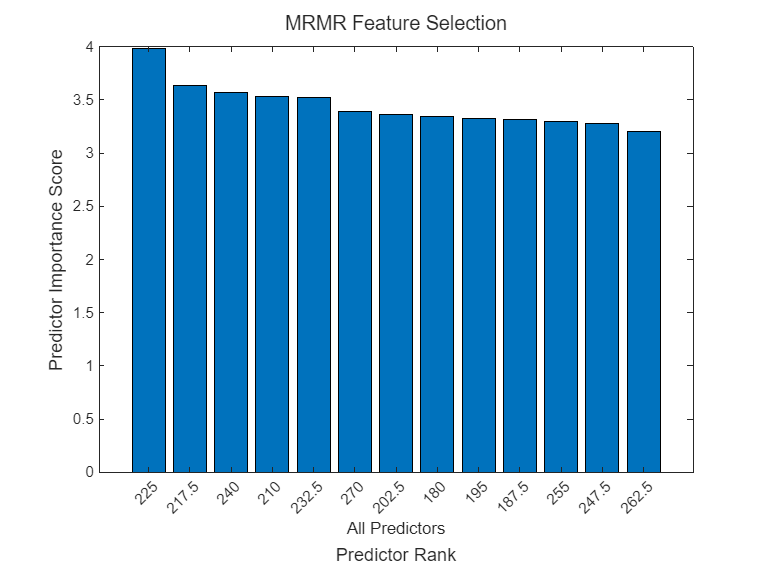

[idx1,scores1] = fsrmrmr(T_val_13,"T_value"); % MRMR feature selection
mrmr_visualization(idx1,scores1,T_val_13) % MRMR visualization

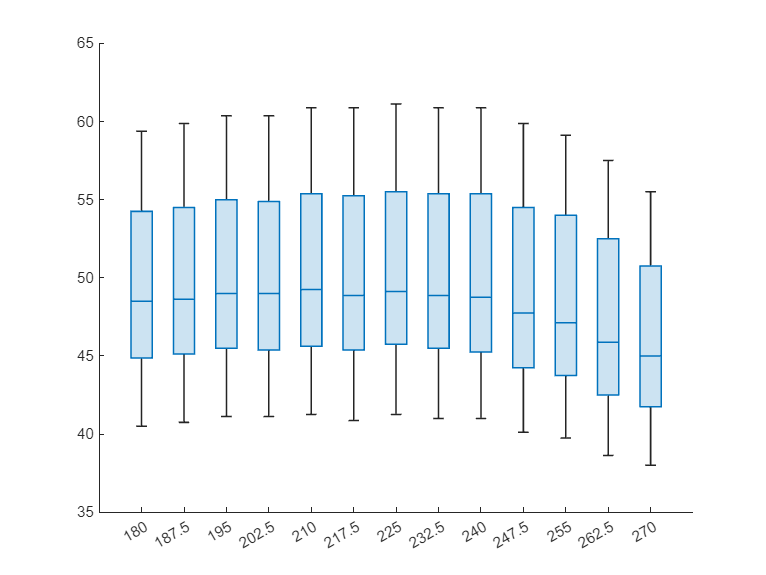

figure;
boxchart(table2array(T_val_13(:,1:end-1))) % 各个predictor的取值分布
xticklabels(string(180:7.5:270))

T_pos_13

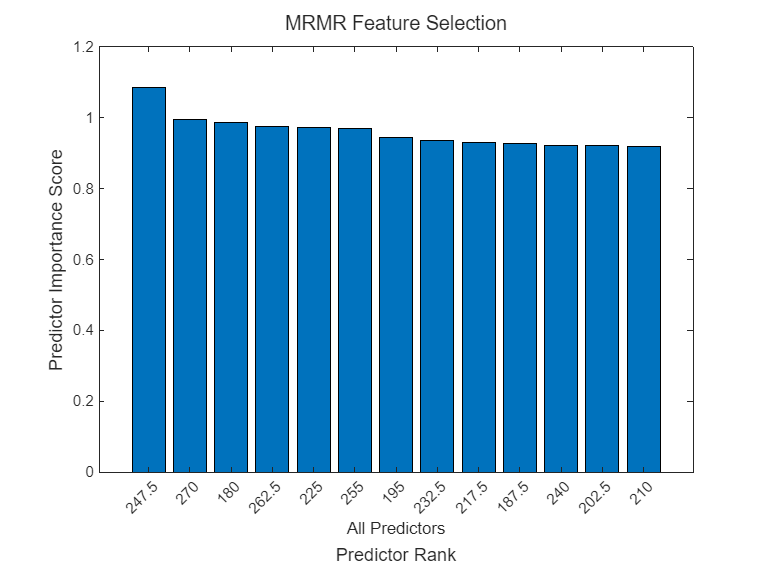

[idx2,scores2] = fsrmrmr(T_pos_13,"T_position"); % MRMR feature selection
mrmr_visualization(idx2,scores2,T_pos_13) % MRMR feature visualization

figure;
boxchart(table2array(T_pos_13(:,1:end-1))) % 各个predictor的取值分布
xticklabels(string(180:7.5:270))

T_pos_14

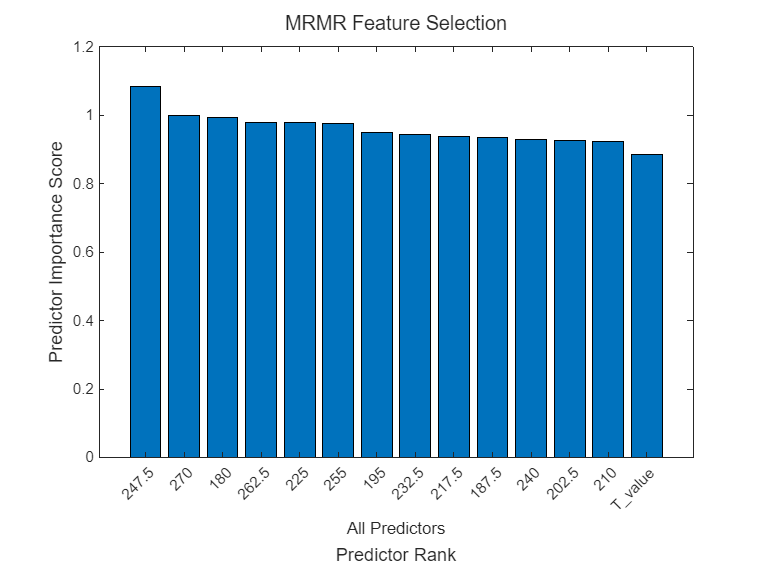

[idx3,scores3] = fsrmrmr(T_pos_14,"T_position"); % MRMR feature selection
mrmr_visualization(idx3,scores3,T_pos_14) % MRMR feature visualization

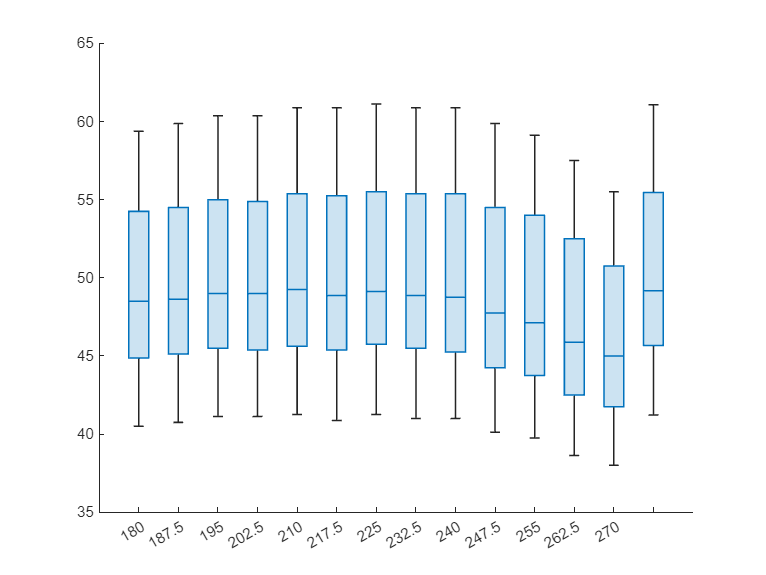

figure;
boxchart(table2array(T_pos_14(:,1:end-1))) % 各个predictor的取值分布
xticklabels(string(180:7.5:270))

**看看六次多项式拟合的RMSE的分布, 作为评价T_max值拟合精度的标准**

load 'processed data'\polynomial_fitted\tableStruct4_6th.mat

% 提取所有的RMSE
RMSE_tbl = [tableStruct4(1).RMSE;
    tableStruct4(2).RMSE;
    tableStruct4(3).RMSE;
    tableStruct4(4).RMSE];
head(RMSE_tbl)

     RMSE  
    _______

    0.12716
    0.12381
    0.11648
     0.1172
    0.13686
    0.11675
    0.11878
    0.10968



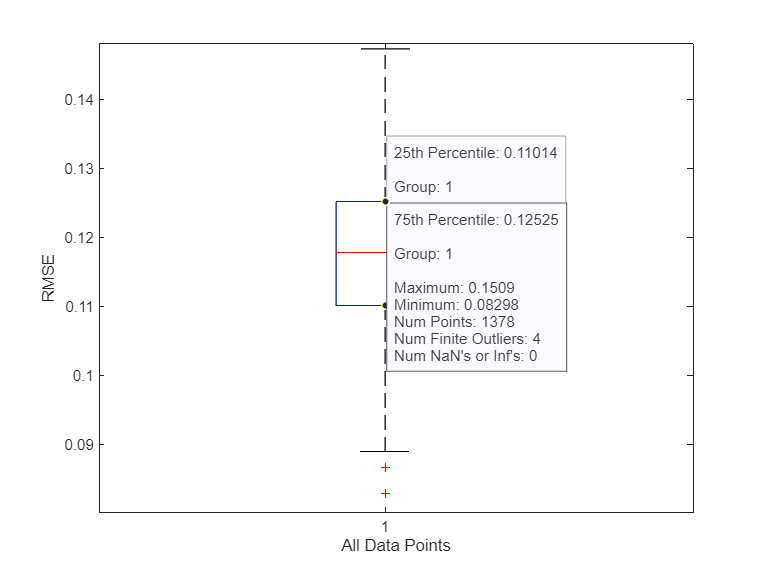


% 画boxplot
boxplot(RMSE_tbl{:,:})
xlabel("All Data Points")
ylabel("RMSE")


IQR = iqr(RMSE_tbl{:,:}) % interquartile range

IQR = 0.0151

min = min(RMSE_tbl{:,:})

min = 0.0830

max = max(RMSE_tbl{:,:})

max = 0.1509

**Interpretation**:

共1378个数据点，其中有4个outlier。

Q1: 0.11014

中数：0.11782

Q3: 0.12525

nonoutlier minimum: 0.089022

nonoutlier maximum: 0.14735

99.71% 的RMSE位于0.089022和0.14735之间